Predict the proportions for the color

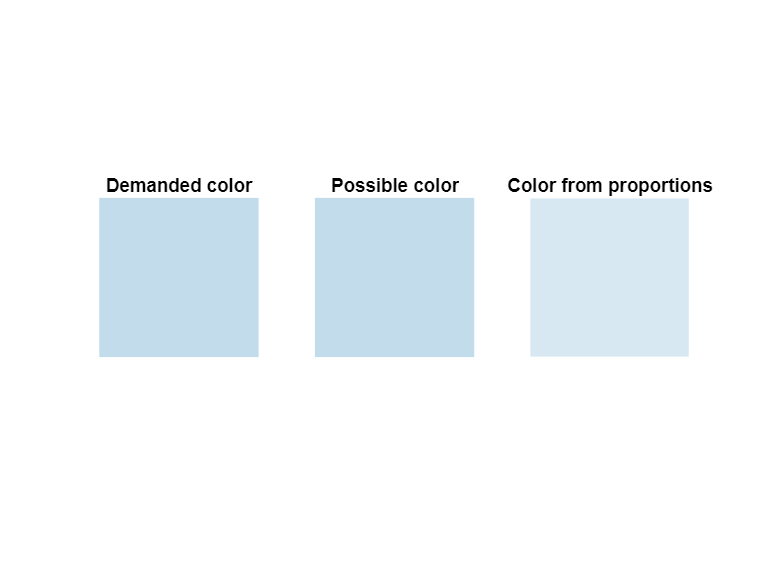

tablename = 'ModelTable600.xls';
Ycell = cell(1,4); % 0 1 2 3 = MY1 MY2 CY CM
Wcell = cell(1,4);

for i = 1:4
    M1 = readmatrix(tablename,'Sheet',i);
    Ycell{i} = M1(:,1:3);
    Wcell{i} = M1(:,4:6);
end

%create HSV color
H = 0.56;
S = 0.17;
V = 0.92;

%convert to RGB
rgbcol = hsv2rgb([H S V]);
labcol = rgb2lab(hsv2rgb([H S V]));

labcol = (labcol + 100)/200; %make positive from 0 to 1
for i = 1:4
    M1 = Ycell{i};
    [n,~] = size(M1);
    M2 = M1;
    for j = 1:n
        labcur = rgb2lab(hsv2rgb(M1(j,:)));

        labcur = (labcur + 100)/200; %make positive from 0 to 1
        M2(j,:) = labcur;
    end
    Ycell{i} = M2;
end

[props, cls, labnew] = PredictProportions(labcol,Ycell,Wcell);
rgbnew = lab2rgb(labnew*200 - 100);
col8 = prop2pp(props,cls);

[lab2,props2] = col82hsv(col8,Wcell,Ycell);
sat = @(x) min(max(x, 0), 1); %saturation function
rgb2 = sat(lab2rgb(lab2*200 - 100));
strcol = '';
for i = 1:3
    strcol = [strcol,' ',num2str(props2(i))];
end

N = 100;

img = double(zeros(N,N,3));
imgnew = img;
img2 = img;
for i = 1:3
    img(:,:,i) = rgbcol(i)*ones(N);
    imgnew(:,:,i) = rgbnew(i)*ones(N);
    img2(:,:,i)= rgb2(i)*ones(N);
end
figure;
subplot(1,3,1);
imshow(img);
title('Demanded color');
subplot(1,3,2);
imshow(imgnew);
title('Possible color');
subplot(1,3,3);
imshow(img2);
title('Color from proportions');


hsvnew = rgb2hsv(rgbnew);
hsv2 = rgb2hsv(rgb2);
disp(['HSV___ = [',num2str(H),' ',num2str(S),' ',num2str(V),']']);

HSV___ = [0.56 0.17 0.92]


disp(['HSVnew = [',num2str(hsvnew(1)),' ',num2str(hsvnew(2)),' ',num2str(hsvnew(3)),']']);

HSVnew = [0.56 0.17 0.92]


disp(['Props = [',strcol,']']);

Props = [ 0.79412 0 0.034023]


disp(['HSV2 = [',num2str(hsv2(1)),' ',num2str(hsv2(2)),' ',num2str(hsv2(3)),']']);

HSV2 = [0.56708 0.10776 0.95079]



switch cls
    case {1,2}
        v1 = 'M/(M + Y)';
    case 3
        v1 = 'Y/(Y + C)';
    case 4
        v1 = 'C/(C + M)';
end
T = table(props(1),props(2),props(3), 'VariableNames',{v1, 'b/(b + w)', 'hue/all'});
disp(T);

    C/(C + M)    b/(b + w)     hue/all 
    _________    __________    ________

     0.79274     0.00032661    0.034172



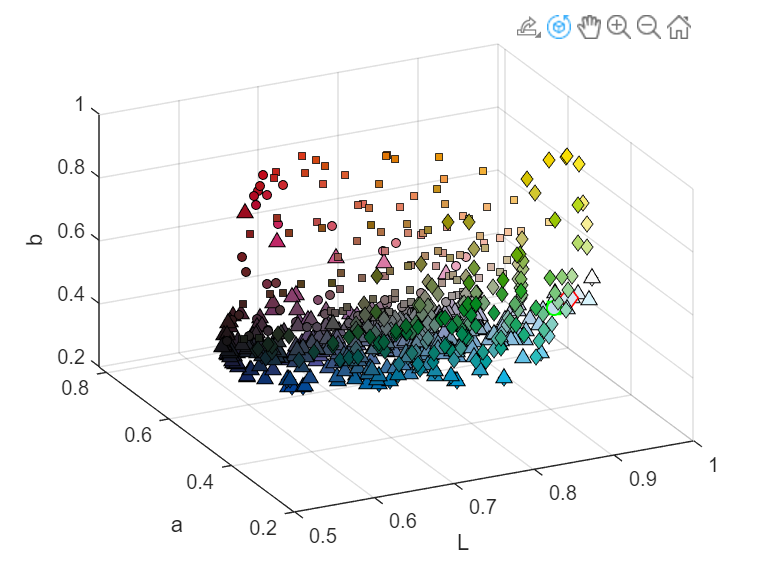


show3d = true;
if show3d
    figure;
    markers = {'o','s','d','^'};
    markersizes = {20,20,30,50};

%     i = cls;
%     Y = Ycell{i}; %RGB
%     W = Wcell{i}; %props
%     scatter3(W(:,1),W(:,2),W(:,3),markersizes{i},Y,markers{i},'filled','MarkerEdgeColor','k'); hold on
%     xlabel('a');
%     ylabel('b');
%     zlabel('c');
%     scatter3(props(1),props(2),props(3),70,rgbcol,'d','filled','MarkerEdgeColor','r','LineWidth',1);


    for i = 1:4
        Y = Ycell{i}; %RGB
        scatter3(Y(:,1),Y(:,2),Y(:,3),markersizes{i},lab2rgb(Y*200 - 100),markers{i},'filled','MarkerEdgeColor','k'); hold on
    end
    xlabel('L');
    ylabel('a');
    zlabel('b');

    scatter3(labcol(1),labcol(2),labcol(3),70,rgbcol,'s','filled','MarkerEdgeColor','g','LineWidth',1);
    scatter3(labnew(1),labnew(2),labnew(3),50,rgbnew,'o','filled','MarkerEdgeColor','g','LineWidth',1);
    scatter3(lab2(1),lab2(2),lab2(3),70,rgb2,'d','filled','MarkerEdgeColor','r','LineWidth',1);

end